# 2D Mie Scattering

[Mie scattering](https://en.wikipedia.org/wiki/Mie_scattering) (also know as Mie solution) describes the scattering of an electromagnetic plane wave by a homogeneous sphere. The solution takes the form of an infinite series of spherical multipole partial waves.

In this example, we show the Mie scattering field of a homogenious 2D cylinder (infinite along $z$) with planar incident wave. All materials in the simulation are assumed to be linear, homogeneous, and isotropic (LHI).

### Step 0: Global settings

The simulation begins with the initialization of a `Model2D` instance, followed by defining the global settings. The working plane is set to the **x-y plane** using the label `'xy'`, which specifies the 2D cross-sectional area for analysis. The simulation is performed for the wavelength of 800** nm**. These global settings provide the foundation for defining the geometry and material properties in subsequent steps.

modelC = Model2D.initialize();

Model2D: Object Reset and Initialized


modelC.setLabel('xy');
modelC.setWavelength(0.55e-6);

### Step 1: Set up the cylindrical scatterer

#### 1.1 Geometry parameters

The radius of the cylinder is set to be **0.6** **µm, **while the center is located at (0,0).

% geometry parameters [unit: m]
radius = 0.6e-6;
position = [0, 0]; % [x, y]

#### 1.2 Material information

The cylinder is made of **fused silica** while the surrounding enviroment is **air**. At $\lambda =0\ldotp 8$**µm**, the refractive indices are $n_{FS} = 1.4533$.

% material
eps_fs = 1.4533^2; % Fused silica
eps_air = 1; % Air

#### 1.3 Construct simulation device

Construct the entire simulation device by creating each of them (air enviroment and silicon cylinder) individually and combining them together.

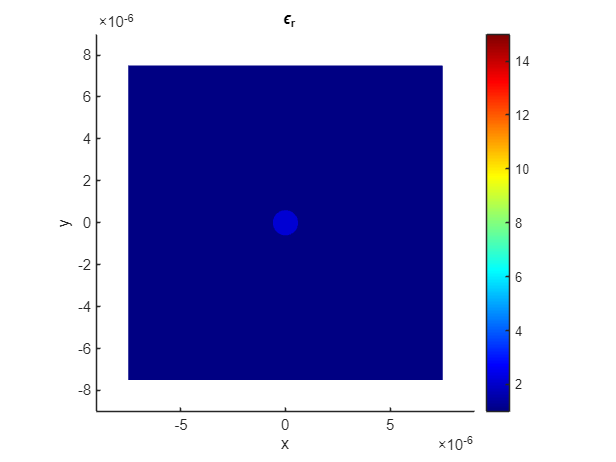

% build air background
modelC.addDevice(1);
modelC.setDevice(1).setGeometry('Rectangle', 15e-6, 15e-6, 'c', [0, 0]);
modelC.setDevice(1).setMaterial(eps_air);

% build cylinder
modelC.addDevice(2);
modelC.setDevice(2).setGeometry('Disk', radius, position);
modelC.setDevice(2).setMaterial(eps_fs);

% complete device
modelC.assembleDevice;
modelC.device.dispImg;

### Step 3: FDFD region mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

The FDFD region is set in the $x-y$ plane with grid sizes ${\rm d}x = {\rm d}y = 30 {\rm nm}$.

% mesh grid
dx = 30e-9;
dy = 30e-9;

Nx = 401;
Ny = 401;

modelC.setMesh([Nx, Ny], [dx, dy]);

### Step 4: Set up FDFD solver

We are going to solve a scattering problem. Therefore, we need to choose `'Scattering' `solver here.

A crucial aspect of the setup involves defining **Perfectly Matched Layers (PML)** around the device. These layers absorb outgoing waves and prevent reflections at the boundaries, ensuring accurate simulation results.

pml_thickness = [10,10];

modelC.setSolver("Scattering", pml_thickness);

### Step 5: Set port

The port must be defined inside the FDFD region. For this example, we show the case of injecting source aling $y$ axis. 

modelC.addPort('+y', -4.5e-6, [-5.7e-6, 5.7e-6]);

Something needs to be noted here: though port is supposed to be as wide as possible to simulate plane-wave situation,  port shouldn't be overlaped within PML region. Be careful when setting the size of port.

### Step 6: Configure input source

Mie scattering discusses theoretical solution of scattering with plane-wave injection. Therefore, we set the source type as TE mode '`PlaneWave'`. 

% plane wave
amp = 1; % amplitude
modelC.addSource('PlaneWave', 'TE', amp);

Source has been set and ready to be used.


% tilte source
theta = 0;
modelC.setSource.setAngle(theta);

### Step 7: 2D scattering simulation

Before simulating the scattering field, make the device is fully meshed, and the input source properly configured. Then call method `'solve'` in `model `object to launch solver. 

modelC.solve;

When the solving is completed, we can export simulation results and visulize them.

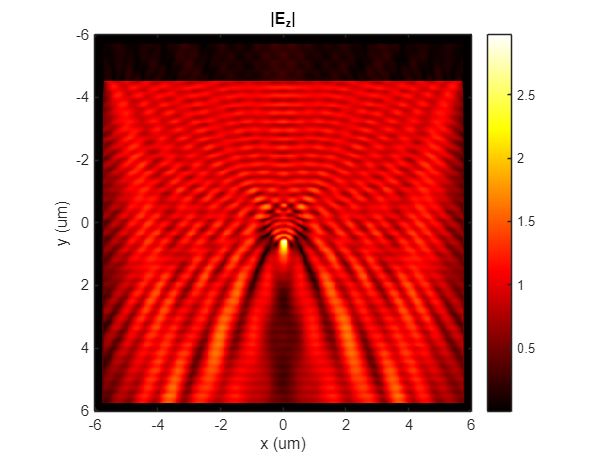

solution = modelC.exportResult;

figure;
imagesc(solution.x*1e6, solution.y*1e6, abs(solution.Ez).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('|E_z|');
colormap hot; colorbar;